# Core Tasks

## Task 1- Load and plot the MRI volumes and masks

loadData

### Visualise slice of 1st healthy and pre-eclampsia sample

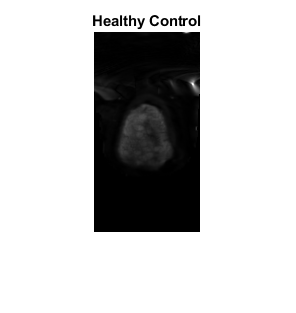


slice_num = 7;
imshow(flipud(squeeze(V_healthy(:,:,slice_num,1))), []);
title("Healthy Control");

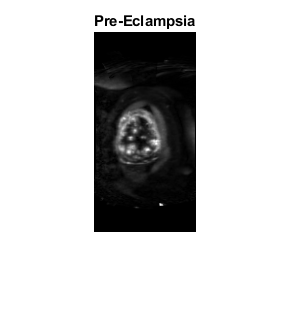

imshow(flipud(squeeze(V_pre_eclampsia(:,:,slice_num,1))), []);
title("Pre-Eclampsia");

## Visualise placenta and uterine wall masks

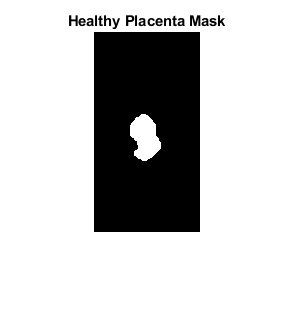

imshow(flipud(squeeze(M_healthy_placenta(:,:,slice_num))), []);
title("Healthy Placenta Mask");

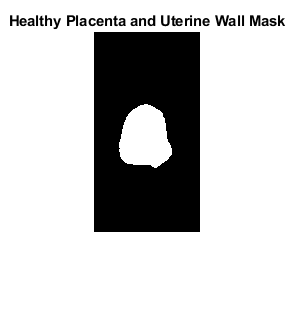

imshow(flipud(squeeze(M_healthy_placenta_uterine_wall(:,:,slice_num))), []); % larger
title("Healthy Placenta and Uterine Wall Mask");

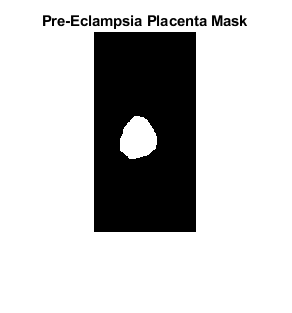

imshow(flipud(squeeze(M_pre_eclampsia_placenta(:,:,slice_num))), []);
title("Pre-Eclampsia Placenta Mask");

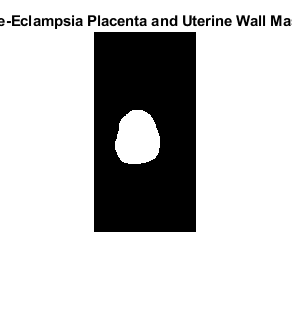

figure(4);
imshow(flipud(squeeze(M_pre_eclampsia_placenta_uterine_wall(:,:,slice_num))), []);
title("Pre-Eclampsia Placenta and Uterine Wall Mask");

## Task 2- Load and plot the MRI acquisition parameters

Each row of MRI params associated with sample from volume

size(grad_echo)

ans =    330     5


size(V_healthy)

ans =    200   106    30   330


unique_b_values_number = numel(unique(grad_echo(:,4)))

unique_b_values_number = 14

unique_echo_times_number = numel(unique(grad_echo(:,5)))

unique_echo_times_number = 5

Visualise MRI params

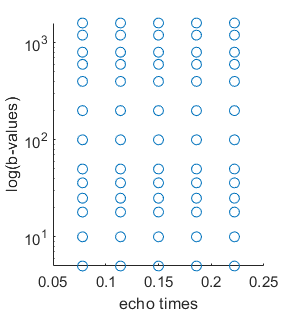

x = grad_echo(:,5);
y = grad_echo(:,4);
scatter(x,y);
set(gca, 'YScale', 'log')
xlabel("echo times");
ylabel("log(b-values)");

## Task 3- Fit combined T2*-ADC model

Init objects

model = T2ADCModel();
non_lin_optimiser = NonLinearOptimiser();

### Single voxel single run fit

Fit model to single voxel of healthy data

non_zero_voxels = reshape(nonzeros(ROI_healthy_placenta_uterine_wall), [], num_scans);
sample_voxel = non_zero_voxels(1, :)';
start_params_T2ADC = [100 0.01 0.001];
start_params_constr_space = T2ADCModel.to_constr_space(start_params_T2ADC);

[params_contr, SSD] = non_lin_optimiser.model_to_voxel(@model.predict, sample_voxel, bvals, TE, start_params_constr_space);

Print parameters

params_fitted = T2ADCModel.to_param_space(params_contr)

params_fitted =   230.3268    0.0307    0.0012


SSD

SSD = 4.8936e+03

Visualise fit

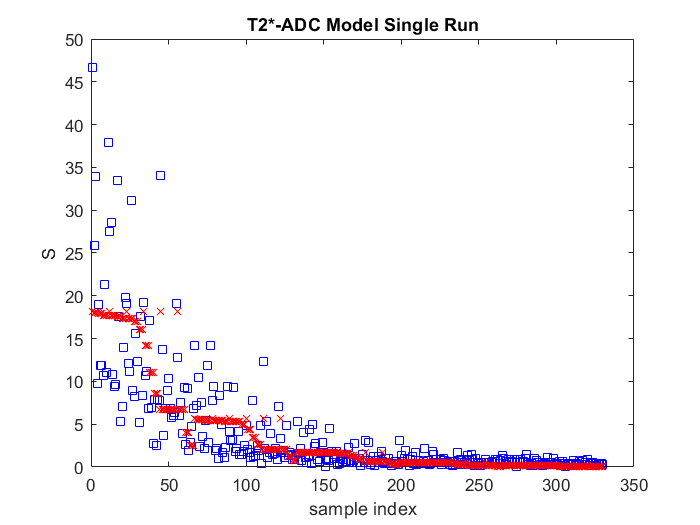

S_predicted = model.predict(params_contr, bvals, TE);
figure();
visualise_model_voxel_fit(S_predicted, sample_voxel, "T2*-ADC Model Single Run")

### Constrained Single voxel multi run fit

pertubation_sigmas_constr_space = T2ADCModel.to_constr_space([50 0.01 0.001]);
[sorted_SSD, sorted_parameters] = non_lin_optimiser.multirun_exploritory(model, sample_voxel, bvals, TE, start_params_constr_space, pertubation_sigmas_constr_space);

Print model parameters

parameters = T2ADCModel.to_param_space(sorted_parameters(1, :))

parameters =   230.3256    0.0307    0.0012


SSD = sorted_SSD(1)

SSD = 4.8936e+03

numRuns = num_runs_to_get_min_95_percent_time(sorted_SSD)

occurance_min = 0.7100

numRuns = 2.4201

Visualise fit

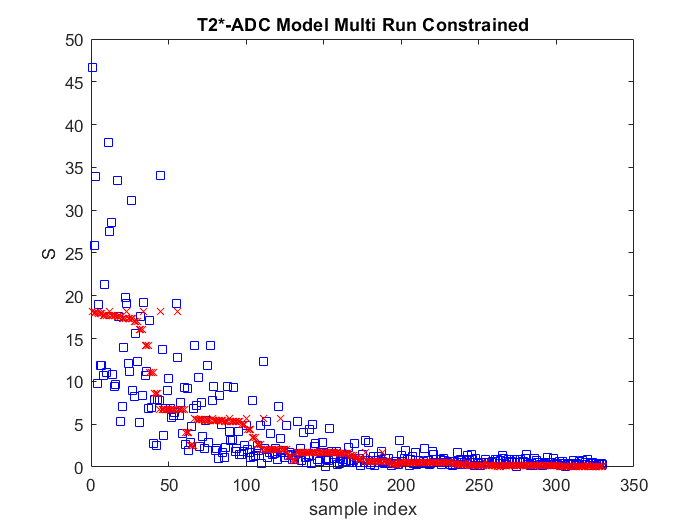

best_fit = model.predict(sorted_parameters(1, :), bvals, TE);
visualise_model_voxel_fit(best_fit, sample_voxel, "T2*-ADC Model Multi Run Constrained");

### Fit Pre Healthy Placenta with Uterine Wall (Single Slice)

Run fit

num_loops = 5; % Set based of previous experiments
slice_of_interest_h_uw = ROI_healthy_placenta_uterine_wall(:,:,slice_num, :);
[parameter_map_h_uw_T2ADC, best_SSD_map_h_uw_T2ADC] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_h_uw, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

### Fit Healthy Placenta with no Uterine Wall (Single Slice)

slice_of_interest_h = ROI_healthy_placenta(:,:,slice_num, :);
[parameter_map_h_T2ADC, best_SSD_map_h_T2ADC] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_h, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

### Fit Pre Exclampsia Placenta with Uterine Wall (Single Slice)

slice_of_interest_pe_uw = ROI_pre_eclampsia_placenta_uterine_wall(:,:,slice_num, :);
[parameter_map_pe_uw_T2ADC, best_SSD_map_pe_uw_T2ADC] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_pe_uw, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

### Fit Pre Exclampsia Placenta with no Uterine Wall (Single Slice)

slice_of_interest_pe = ROI_pre_eclampsia_placenta(:,:,slice_num, :);
[parameter_map_pe_T2ADC, best_SSD_map_pe_T2ADC] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_pe, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

## Task 4- Visualise and Compare Healthy and Pre-Eclampsia Maps

Combine all maps into a single 4D array

num_maps = 4;
param_maps_T2ADC=zeros([num_maps, size(parameter_map_h_T2ADC)]);
param_maps_T2ADC(1,:,:,:) = parameter_map_h_T2ADC(:,:,:);
param_maps_T2ADC(2,:, 1:size(parameter_map_pe_T2ADC,2), 1:size(parameter_map_pe_T2ADC,3)) = parameter_map_pe_T2ADC(:,:,:);
param_maps_T2ADC(3,:,:,:) = parameter_map_h_uw_T2ADC(:,:,:);
param_maps_T2ADC(4,:, 1:size(parameter_map_pe_uw_T2ADC,2), 1:size(parameter_map_pe_uw_T2ADC,3)) = parameter_map_pe_uw_T2ADC(:,:,:);

Define labels for plot

param_labels = ["S_0", "T2*", "D"];
map_labels = ["Healthy", "Pre-Eclampsia", "Healthy with UW", "Pre-Eclampsia with UW"];
param_units = ["AU", "s", "mm^2s^{-1}"];

Plot maps

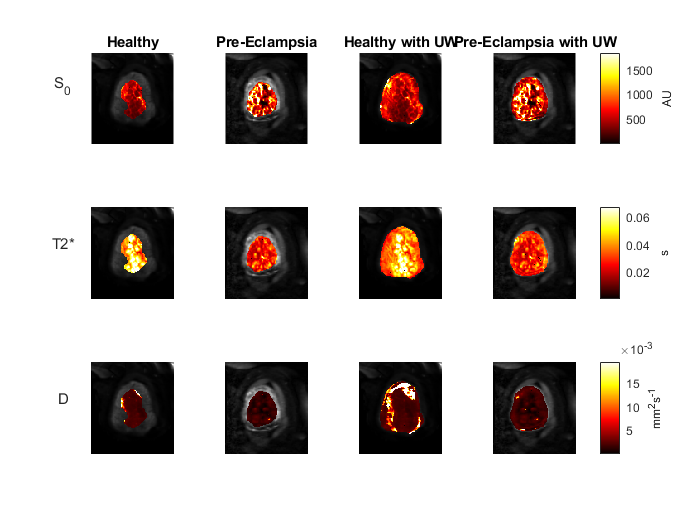

figure();
Plotter.visualise_param_maps(param_maps_T2ADC, squeeze(V_healthy(:,:,slice_num,1)), squeeze(V_pre_eclampsia(:,:,slice_num,1)), param_labels, map_labels, param_units)

Plot box plots of parameters

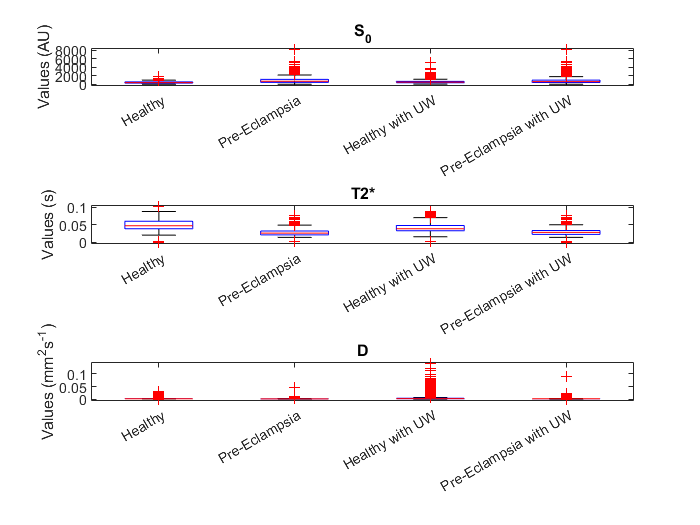

figure();
Plotter.box_plot_param_maps(param_maps_T2ADC, param_labels, map_labels, param_units)

## Task 5- IVIM Model

model = IVIMModel();

### Single voxel single run fit

Fit model to single voxel of healthy data

start_params_IVIM = [100 0.01 0.001 0.5 0.01];
start_params_constr_space = IVIMModel.to_constr_space(start_params_IVIM);
[params_contr, SSD] = non_lin_optimiser.model_to_voxel(@model.predict, sample_voxel, bvals, TE, start_params_constr_space);

Print parameters

params_fitted = IVIMModel.to_param_space(params_contr)

params_fitted =   318.2491    0.0308    0.0005    0.5637    0.0433


SSD

SSD = 4.0746e+03

Visualise fit

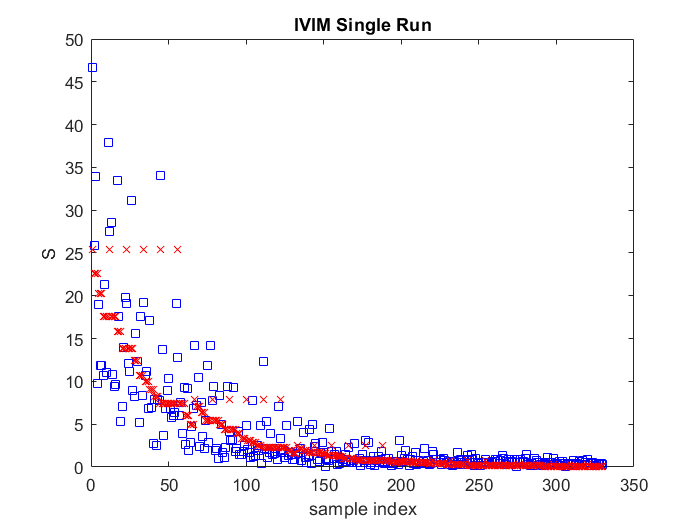

S_predicted = model.predict(params_contr, bvals, TE);
figure();
visualise_model_voxel_fit(S_predicted, sample_voxel, "IVIM Single Run")

### Constrained Single voxel multi run fit

pertubation_sigmas_constr_space = IVIMModel.to_constr_space([50 0.01 0.001 0.1 0.01]);
[sorted_SSD, sorted_parameters] = non_lin_optimiser.multirun_exploritory(model, sample_voxel, bvals, TE, start_params_constr_space, pertubation_sigmas_constr_space);

Print model parameters

parameters = IVIMModel.to_param_space(sorted_parameters(1, :))

parameters =   318.2478    0.0308    0.0005    0.5637    0.0433


SSD = sorted_SSD(1)

SSD = 4.0746e+03

numRuns = num_runs_to_get_min_95_percent_time(sorted_SSD)

occurance_min = 0.6700

numRuns = 2.7021

Visualise fit

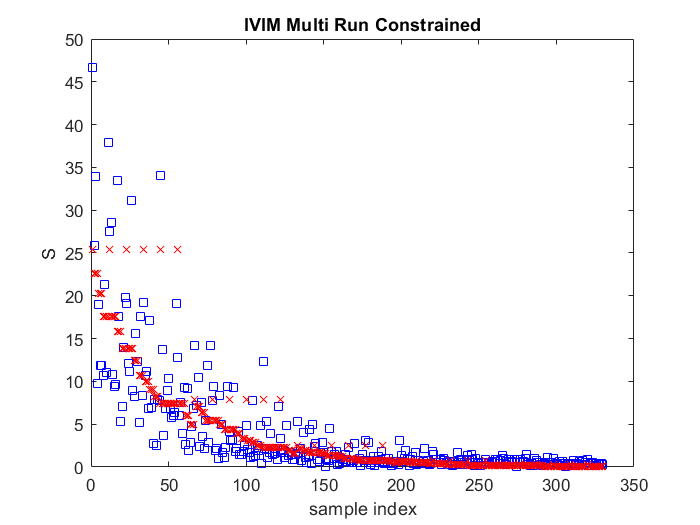

best_fit = model.predict(sorted_parameters(1, :), bvals, TE);
visualise_model_voxel_fit(best_fit, sample_voxel, "IVIM Multi Run Constrained");

### Fit Pre Healthy Placenta with Uterine Wall (Single Slice)

Run fit

slice_of_interest_h_uw = ROI_healthy_placenta_uterine_wall(:,:,slice_num, :);
[parameter_map_h_uw_IVIM, best_SSD_map_h_uw_IVIM] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_h_uw, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

### Fit Healthy Placenta with no Uterine Wall (Single Slice)

slice_of_interest_h = ROI_healthy_placenta(:,:,slice_num, :);
[parameter_map_h_IVIM, best_SSD_map_h_IVIM] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_h, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

### Fit Pre Exclampsia Placenta with Uterine Wall (Single Slice)

slice_of_interest_pe_uw = ROI_pre_eclampsia_placenta_uterine_wall(:,:,slice_num, :);
[parameter_map_pe_uw_IVIM, best_SSD_map_pe_uw_IVIM] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_pe_uw, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

### Fit Pre Exclampsia Placenta with no Uterine Wall (Single Slice)

slice_of_interest_pe = ROI_pre_eclampsia_placenta(:,:,slice_num, :);
[parameter_map_pe_IVIM, best_SSD_map_pe_IVIM] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_pe, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

Combine all maps into a single 4D array

param_maps_IVIM=zeros([4, size(parameter_map_h_IVIM)]);
param_maps_IVIM(1,:,:,:) = parameter_map_h_IVIM(:,:,:);
param_maps_IVIM(2,:, 1:size(parameter_map_pe_IVIM,2), 1:size(parameter_map_pe_IVIM,3)) = parameter_map_pe_IVIM(:,:,:);
param_maps_IVIM(3,:,:,:) = parameter_map_h_uw_IVIM(:,:,:);
param_maps_IVIM(4,:, 1:size(parameter_map_pe_uw_IVIM,2), 1:size(parameter_map_pe_uw_IVIM,3)) = parameter_map_pe_uw_IVIM(:,:,:);

Define labels for plot

param_labels = ["S_0", "T2*", "D", "f", "D_p"];
map_labels = ["Healthy", "Pre-Eclampsia", "Healthy with UW", "Pre-Eclampsia with UW"];
param_units = ["AU", "s", "mm^2s^{-1}", "", "mm^2s^{-1}"];

Plot maps

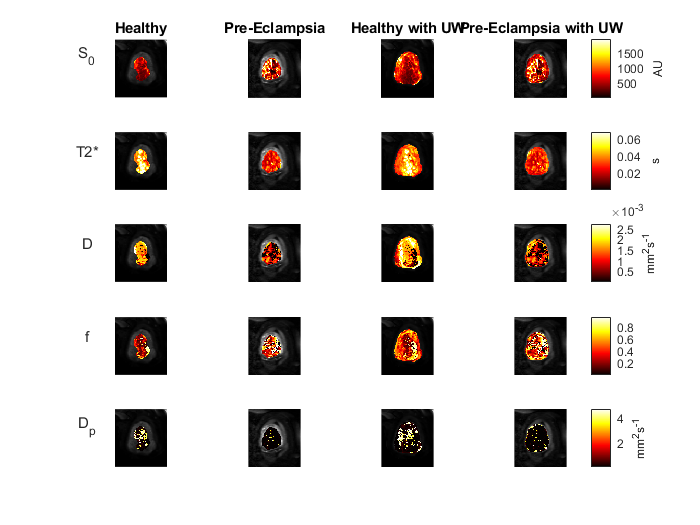

figure();
tiledlayout(size(param_maps_IVIM,2),num_maps);
Plotter.visualise_param_maps(param_maps_IVIM, squeeze(V_healthy(:,:,slice_num,1)), squeeze(V_pre_eclampsia(:,:,slice_num,1)), param_labels, map_labels, param_units)

Plot box plots of parameters

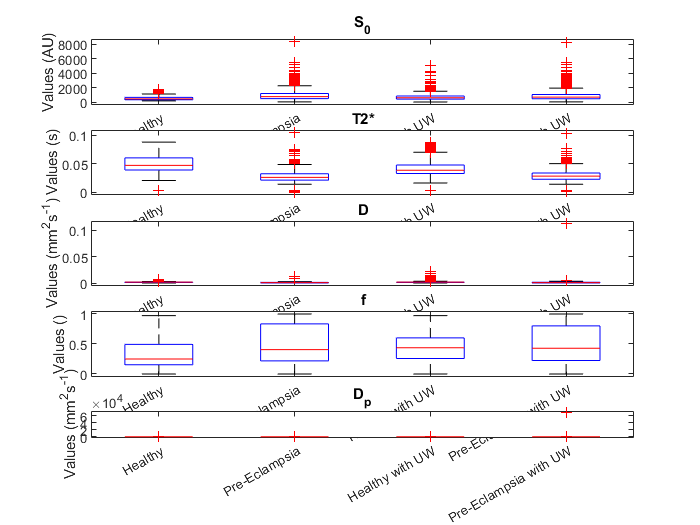

figure();
Plotter.box_plot_param_maps(param_maps_IVIM, param_labels, map_labels, param_units)

## Task 7- Continuum Model

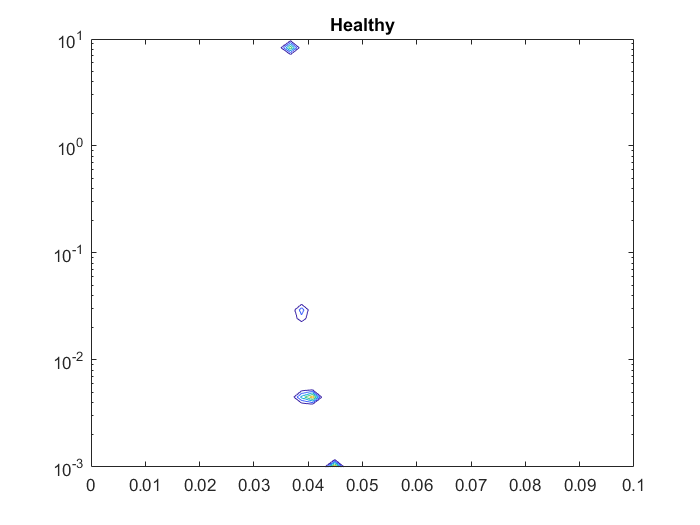

T2_values = linspace(0.0, 0.1, 50);
D_values = logspace(-3, 1, 50);
ROI = ROI_healthy_placenta_uterine_wall;
spectrum = ContinuumModel.calc_spectrum(T2_values, D_values, ROI, bvals, TE);
figure();
contour(T2_values, D_values, spectrum)
title("Healthy")
set(gca, 'YScale', 'log')

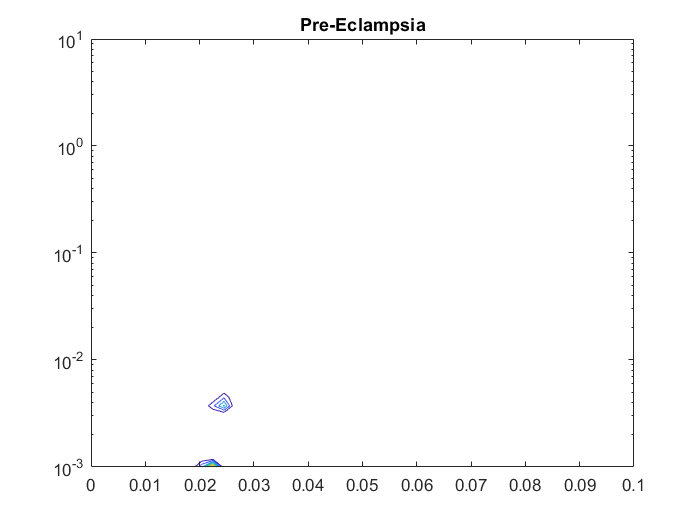

ROI = ROI_pre_eclampsia_placenta_uterine_wall;
spectrum = ContinuumModel.calc_spectrum(T2_values, D_values, ROI, bvals, TE);
figure();
contour(T2_values, D_values, spectrum)
title("Pre-Eclampsia")
set(gca, 'YScale', 'log')

## Task 8- Three Compartment Model

model = ThreeCompModel();

### Single voxel single run fit

Fit model to single voxel of healthy data

start_params_3_Comp = [100 0.01 0.001 0.5 0.01 0.5 1];
start_params_constr_space = ThreeCompModel.to_constr_space(start_params_3_Comp);
[params_contr, SSD] = non_lin_optimiser.model_to_voxel(@model.predict, sample_voxel, bvals, TE, start_params_constr_space);

Print parameters

params_fitted = ThreeCompModel.to_param_space(params_contr)

params_fitted =   318.3464    0.0308    0.0005    0.4349    0.0044    0.0050    0.0435


SSD

SSD = 4.0746e+03

Visualise fit

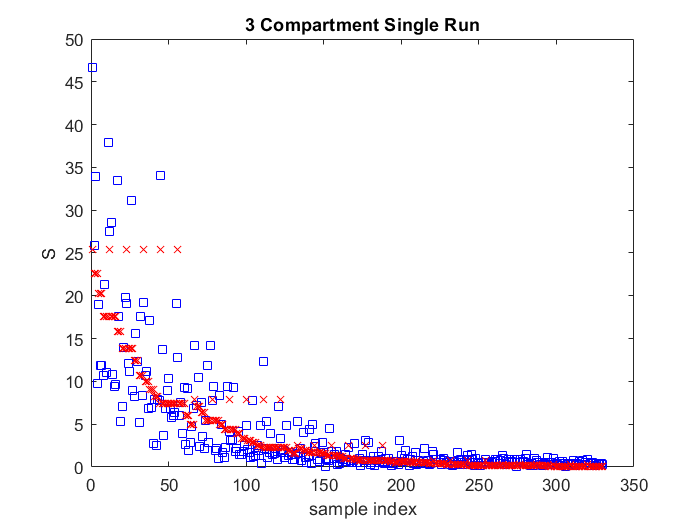

S_predicted = model.predict(params_contr, bvals, TE);
figure();
visualise_model_voxel_fit(S_predicted, sample_voxel, "3 Compartment Single Run")

### Constrained Single voxel multi run fit

pertubation_sigmas_constr_space = abs(ThreeCompModel.to_constr_space([50 0.01 0.0001 0.1 0.001 0.1 0.1]))

pertubation_sigmas_constr_space =     7.0711    0.1002    0.1002    0.3218    0.0300    0.3218    0.0997


[sorted_SSD, sorted_parameters] = non_lin_optimiser.multirun_exploritory(model, sample_voxel, bvals, TE, start_params_constr_space, pertubation_sigmas_constr_space);

Print model parameters

parameters = ThreeCompModel.to_param_space(sorted_parameters(1, :))

parameters =   333.8572    0.0308    0.0004    0.3874    0.0237    0.6412    0.2562


SSD = sorted_SSD(1)

SSD = 4.0300e+03

numRuns = num_runs_to_get_min_95_percent_time(sorted_SSD)

occurance_min = 0.6300

numRuns = 3.0131

Visualise fit

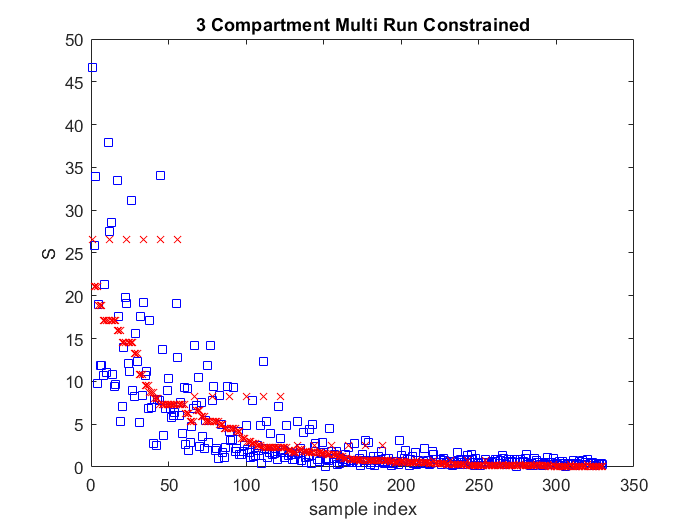

best_fit = model.predict(sorted_parameters(1, :), bvals, TE);
visualise_model_voxel_fit(best_fit, sample_voxel, "3 Compartment Multi Run Constrained");

### Fit Pre Healthy Placenta with Uterine Wall (Single Slice)

Run fit

slice_of_interest_h_uw = ROI_healthy_placenta_uterine_wall(:,:,slice_num, :);
[parameter_map_h_uw_3_comp, best_SSD_map_h_uw_3_comp] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_h_uw, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

### Fit Healthy Placenta with no Uterine Wall (Single Slice)

slice_of_interest_h = ROI_healthy_placenta(:,:,slice_num, :);
[parameter_map_h_3_comp, best_SSD_map_h_3_comp] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_h, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

### Fit Pre Exclampsia Placenta with Uterine Wall (Single Slice)

slice_of_interest_pe_uw = ROI_pre_eclampsia_placenta_uterine_wall(:,:,slice_num, :);
[parameter_map_pe_uw_3_comp, best_SSD_map_pe_uw_3_comp] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_pe_uw, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

### Fit Pre Exclampsia Placenta with no Uterine Wall (Single Slice)

slice_of_interest_pe = ROI_pre_eclampsia_placenta(:,:,slice_num, :);
[parameter_map_pe_3_comp, best_SSD_map_pe_3_comp] = non_lin_optimiser.slice_multi_run(model, slice_of_interest_pe, bvals, TE, start_params_constr_space, num_loops, pertubation_sigmas_constr_space);

row_num = 10

row_num = 20

row_num = 30

row_num = 40

row_num = 50

row_num = 60

row_num = 70

row_num = 80

row_num = 90

row_num = 100

row_num = 110

row_num = 120

row_num = 130

row_num = 140

row_num = 150

row_num = 160

row_num = 170

row_num = 180

row_num = 190

row_num = 200

num_models = 3;
param_maps_all=zeros([num_models*2, size(parameter_map_h_uw_3_comp, 1), size(parameter_map_h_uw_3_comp, 2), size(parameter_map_h_uw_3_comp, 3)]);
% Load T2*-ADC
param_maps_all(1,1:size(parameter_map_h_uw_T2ADC,1),:,:) = parameter_map_h_uw_T2ADC(:,:,:);
param_maps_all(2,1:1:size(parameter_map_pe_uw_T2ADC,1), 1:size(parameter_map_pe_uw_T2ADC,2), 1:size(parameter_map_pe_uw_T2ADC,3)) = parameter_map_pe_uw_T2ADC(:,:,:);
% Load IVIM
param_maps_all(3,1:size(parameter_map_h_uw_IVIM,1),:,:) = parameter_map_h_uw_IVIM(:,:,:);
param_maps_all(4,1:1:size(parameter_map_pe_uw_IVIM,1), 1:size(parameter_map_pe_uw_IVIM,2), 1:size(parameter_map_pe_uw_IVIM,3)) = parameter_map_pe_uw_IVIM(:,:,:);
% Load 3 Compartment
param_maps_all(5,:,:,:) = parameter_map_h_uw_3_comp(:,:,:);
param_maps_all(6,:, 1:size(parameter_map_pe_uw_3_comp,2), 1:size(parameter_map_pe_uw_3_comp,3)) = parameter_map_pe_uw_3_comp(:,:,:);

param_maps_all(:,3, :, :) = log10(param_maps_all(:,3, :, :));
param_maps_all(param_maps_all<-5) = 0;

param_labels = ["S_0", "T2*", "D_1", "f_1", "D_2", "v", "D_3"];
map_labels = ["T2*-ADC Healthy", "T2*-ADC Pre-Eclampsia", "IVIM Healthy", "IVIM Pre-Eclampsia", "3 Compartment Healthy", "3 Compartment Pre-Eclampsia"];
param_units = ["AU", "s", "mm^2s^{-1}", "", "mm^2s^{-1}", "", "mm^2s^{-1}"];

Plot maps

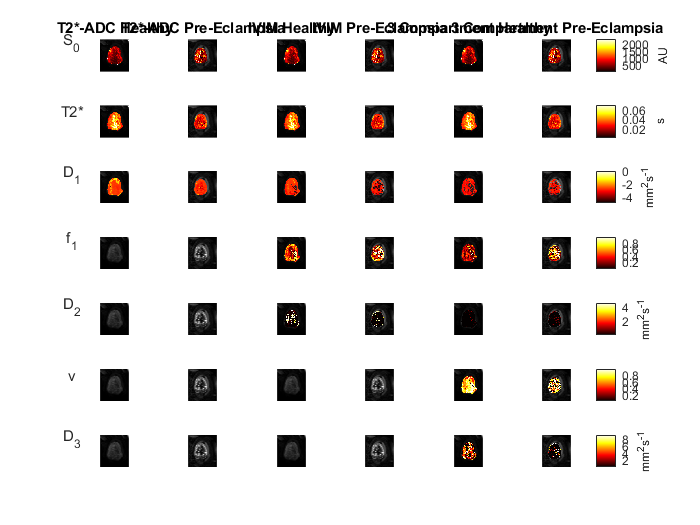

figure();
tiledlayout(size(param_maps_all,2),6);
Plotter.visualise_param_maps(param_maps_all, squeeze(V_healthy(:,:,slice_num,1)), squeeze(V_pre_eclampsia(:,:,slice_num,1)), param_labels, map_labels, param_units)

Combine all maps into a single 4D array

param_maps_3_comp=zeros([4, size(parameter_map_h_uw_3_comp, 1), size(parameter_map_h_uw_3_comp, 2), size(parameter_map_h_uw_3_comp, 3)]);
param_maps_3_comp(1,:,:,:) = parameter_map_h_3_comp(:,:,:);
param_maps_3_comp(2,:, 1:size(parameter_map_pe_3_comp,2), 1:size(parameter_map_pe_3_comp,3)) = parameter_map_pe_3_comp(:,:,:);
param_maps_3_comp(3,:,:,:) = parameter_map_h_uw_3_comp(:,:,:);
param_maps_3_comp(4,:, 1:size(parameter_map_pe_uw_3_comp,2), 1:size(parameter_map_pe_uw_3_comp,3)) = parameter_map_pe_uw_3_comp(:,:,:);

Define labels for plot

param_labels = ["S_0", "T2*", "D_1", "f_1", "D_2", "v", "D_3"];
map_labels = ["Healthy", "Pre-Eclampsia", "Healthy with UW", "Pre-Eclampsia with UW"];
param_units = ["AU", "s", "mm^2s^{-1}", "", "mm^2s^{-1}", "", "mm^2s^{-1}"];

Plot maps

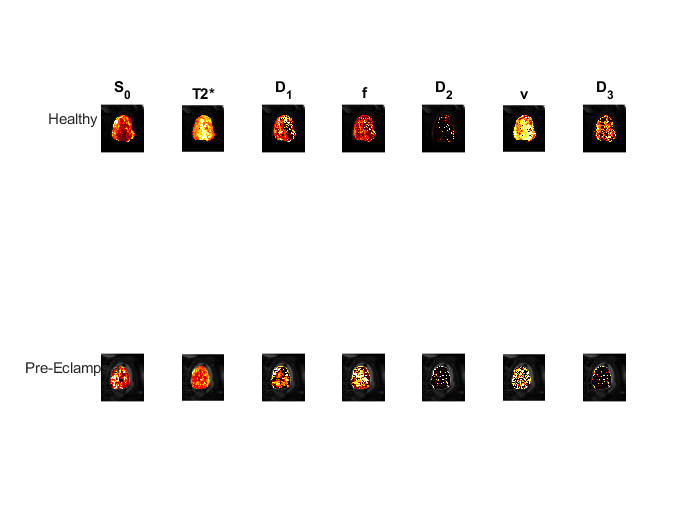

plot_index = 1

plot_index = 8

plot_index = 2

plot_index = 9

plot_index = 3

plot_index = 10

plot_index = 4

plot_index = 11

plot_index = 5

plot_index = 12

plot_index = 6

plot_index = 13

plot_index = 7

plot_index = 14

figure();
tiledlayout(size(param_maps_3_comp,2),num_maps);
Plotter.visualise_param_maps(param_maps_3_comp, squeeze(V_healthy(:,:,slice_num,1)), squeeze(V_pre_eclampsia(:,:,slice_num,1)), param_labels, map_labels, param_units)

Plot box plots of parameters

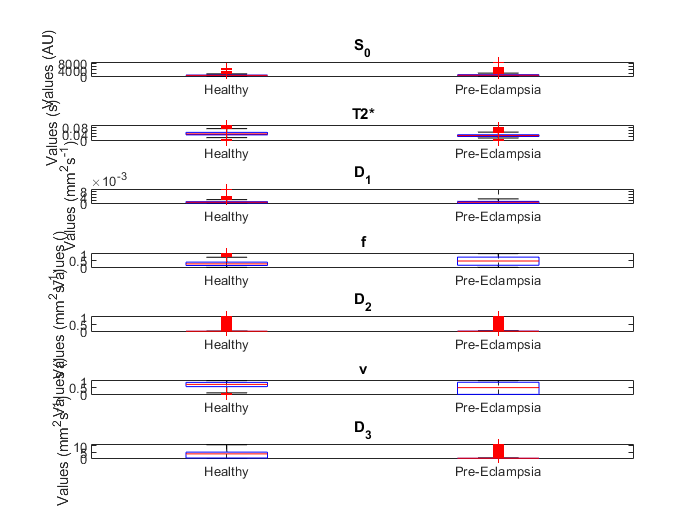

figure();
Plotter.box_plot_param_maps(param_maps_3_comp, param_labels, map_labels, param_units)

## Task 6- BIC

num_models = 3;
num_maps = 4;
num_scans = size(grad_echo,1);

% Collect all SSE maps together
SSE_maps = zeros([num_maps, num_models, size(best_SSD_map_h_uw_T2ADC)]);
SSE_maps(1, 1,:,:) = best_SSD_map_h_T2ADC;
SSE_maps(2, 1, 1:size(best_SSD_map_pe_T2ADC,1), 1:size(best_SSD_map_pe_T2ADC,2)) = best_SSD_map_pe_T2ADC;
SSE_maps(3, 1,:,:) = best_SSD_map_h_uw_T2ADC;
SSE_maps(4, 1, 1:size(best_SSD_map_pe_uw_T2ADC,1), 1:size(best_SSD_map_pe_uw_T2ADC,2)) = best_SSD_map_pe_uw_T2ADC;

SSE_maps(1, 2,:,:) = best_SSD_map_h_IVIM;
SSE_maps(2, 2, 1:size(best_SSD_map_pe_IVIM,1), 1:size(best_SSD_map_pe_IVIM,2)) = best_SSD_map_pe_IVIM;
SSE_maps(3, 2,:,:) = best_SSD_map_h_uw_IVIM;
SSE_maps(4, 2, 1:size(best_SSD_map_pe_uw_IVIM,1), 1:size(best_SSD_map_pe_uw_IVIM,2)) = best_SSD_map_pe_uw_IVIM;

SSE_maps(1, 3,:,:) = best_SSD_map_h_3_comp;
SSE_maps(2, 3, 1:size(best_SSD_map_pe_3_comp,1), 1:size(best_SSD_map_pe_3_comp,2)) = best_SSD_map_pe_3_comp;
SSE_maps(3, 3,:,:) = best_SSD_map_h_uw_3_comp;
SSE_maps(4, 3, 1:size(best_SSD_map_pe_uw_3_comp,1), 1:size(best_SSD_map_pe_uw_3_comp,2)) = best_SSD_map_pe_uw_3_comp;

% Collect all the BIC maps into 1 matrix
BIC_maps = zeros([num_maps, num_models, size(best_SSD_map_h_uw_T2ADC)]);
BIC_maps(1, 1,:,:) = BIC_gaussian(length(start_params_T2ADC), num_scans, best_SSD_map_h_T2ADC);
BIC_maps(2, 1, 1:size(best_SSD_map_pe_T2ADC,1), 1:size(best_SSD_map_pe_T2ADC,2)) = BIC_gaussian(length(start_params_T2ADC), num_scans, best_SSD_map_pe_T2ADC);
BIC_maps(3, 1,:,:) = BIC_gaussian(length(start_params_T2ADC), num_scans, best_SSD_map_h_uw_T2ADC);
BIC_maps(4, 1, 1:size(best_SSD_map_pe_uw_T2ADC,1), 1:size(best_SSD_map_pe_uw_T2ADC,2)) = BIC_gaussian(length(start_params_T2ADC), num_scans, best_SSD_map_pe_uw_T2ADC);

BIC_maps(1, 2,:,:) = BIC_gaussian(length(start_params_IVIM), num_scans, best_SSD_map_h_IVIM);
BIC_maps(2, 2, 1:size(best_SSD_map_pe_IVIM,1), 1:size(best_SSD_map_pe_IVIM,2)) = BIC_gaussian(length(start_params_IVIM), num_scans, best_SSD_map_pe_IVIM);
BIC_maps(3, 2,:,:) = BIC_gaussian(length(start_params_IVIM), num_scans, best_SSD_map_h_uw_IVIM);
BIC_maps(4, 2, 1:size(best_SSD_map_pe_uw_IVIM,1), 1:size(best_SSD_map_pe_uw_IVIM,2)) = BIC_gaussian(length(start_params_IVIM), num_scans, best_SSD_map_pe_uw_IVIM);

BIC_maps(1, 3,:,:) = BIC_gaussian(length(start_params_3_Comp), num_scans, best_SSD_map_h_3_comp);
BIC_maps(2, 3, 1:size(best_SSD_map_pe_3_comp,1), 1:size(best_SSD_map_pe_3_comp,2)) = BIC_gaussian(length(start_params_3_Comp), num_scans, best_SSD_map_pe_3_comp);
BIC_maps(3, 3,:,:) = BIC_gaussian(length(start_params_3_Comp), num_scans, best_SSD_map_h_uw_3_comp);
BIC_maps(4, 3, 1:size(best_SSD_map_pe_uw_3_comp,1), 1:size(best_SSD_map_pe_uw_3_comp,2)) = BIC_gaussian(length(start_params_3_Comp), num_scans, best_SSD_map_pe_uw_3_comp);

Plot maps

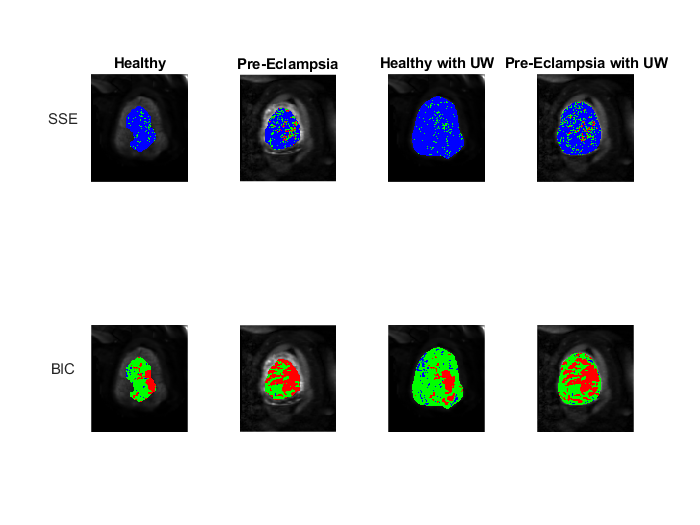

figure();
tiledlayout(2,num_maps);
Plotter.compare_models(SSE_maps, squeeze(V_healthy(:,:,slice_num,1)), squeeze(V_pre_eclampsia(:,:,slice_num,1)), "SSE", map_labels)
Plotter.compare_models(BIC_maps, squeeze(V_healthy(:,:,slice_num,1)), squeeze(V_pre_eclampsia(:,:,slice_num,1)), "BIC", ["","","",""])

sum(SSE_maps, [3,4])

ans = 	1.0e+07 *

    1.7162    1.4473    1.4485
    0.5946    0.5888    0.5608
    4.7419    3.8575    3.9066
    1.1622    1.0381    1.0840


sum(BIC_maps, [3,4])

ans = 	1.0e+06 *

    1.2538    1.2195    1.2301
    0.9233    0.9184    0.9270
    3.2766    3.1383    3.1590
    1.6192    1.5887    1.6114


### Fitting helper funcs

function numRuns = num_runs_to_get_min_95_percent_time(sorted_SSD)
    % Calculated as P(minumum in run) = 1-P(minimum is not in run)
    %               0.95 = 1 - (1-occurance_min)^n
    % Tolerance required as == large floating point numbers (hence high
    % tolerance)
    tol = 10^-01;
    occurance_min = sum(abs(sorted_SSD-sorted_SSD(1)) < tol)/length(sorted_SSD)
    numRuns = log(0.05)/log(1-occurance_min);
end

### Plotting funcs

function visualise_model_voxel_fit(predicted, actual, plot_title)
    plot(actual, ' bs')%, 'MarkerSize', 10, 'Linewidth', 4);
    hold on;
    plot(predicted, ' rx')%, 'MarkerSize', 16, 'Linewidth', 4);
    title(plot_title);
    xlabel('sample index');
    ylabel('S');
    hold off;
end

function plotMaps(parameter_map, SSD_map)
    % Plots parameters as a series of subplots
    S0 = parameter_map(1,:,:);
    T_star = parameter_map(2,:,:);
    d = parameter_map(3,:,:);
    
    plot_parameter(S0, 1, 'S_0');
    plot_parameter(T_star, 2, 'T2^*');
    plot_parameter(d, 3, 'D');
    plot_parameter(SSD_map, 4, 'SSD');
end

function plot_parameter(parameter, subplot_num, subplot_title)
    subplot(2,2,subplot_num);
    % Set upper bound as 10th highest value to handle outliers
    sorted_param = sort(parameter(:));
    imshow(flipud(squeeze(parameter)'), [0 sorted_param(end-25)]);
    title(subplot_title);
end

function BIC = BIC_gaussian(N, K, SSE)
    BIC = zeros(size(SSE));
    BIC = (N+1)*log(K) + K*log(SSE/K);
    BIC(BIC==-Inf) = 0;
end